% function [theta] = J_inverse_kinematics(T_sb,T_sd)

clear
clc

L=[100 265 360 360 175];
omega=[
    0,0,1;%1
    0,1,0;%2
    -1,0,0;%3
    0,0,-1;%4
    1,0,0;%5
    0,0,1;%6
    1,0,0;%7
    0,0,1;%8
    ];
q=[
    [-L(1),0,0];%1
    [0,L(2),0];%2
    [0,L(2),0];%3
    [0,L(2),-L(3)];%4
    [0,L(2),-L(3)];%5
    [0,L(2),-L(3)];%6
    [0,L(2),-L(3)-L(4)];%7
    [0,L(2),-L(3)-L(4)-L(5)];%8
    ];
home=[
    1 0 0 0;
    0 1 0 L(2);
    0 0 1 -L(3)-L(4)-L(5);
    0 0 0 1
    ];
%testing ---------------
T_sb=[1 0 0 0;
    0 1 0 L(2);
    0 0 1 -L(3)-L(4)-L(5);
    0 0 0 1];
T_sd=[1 0 0 0;
    0 1 0 L(3);
    0 0 1 L(4);
    0 0 0 L(5)];
%end of testing --------

%initial guess, setting error criteria
theta=[pi/9 pi/8 pi/7 pi/6 pi/6 pi/7 pi/8 pi/9]

theta =     0.3491    0.3927    0.4488    0.5236    0.5236    0.4488    0.3927    0.3491


i = 1

theta =   -16.9329  -16.8893  -16.8332  -16.7584  -16.7584  -16.8332  -16.8893  -16.9329
    6.5972    6.6408    6.6969    6.7717    6.7717    6.6969    6.6408    6.5972
   20.7517   20.7954   20.8515   20.9263   20.9263   20.8515   20.7954   20.7517
  -10.2172  -10.1736  -10.1175  -10.0427  -10.0427  -10.1175  -10.1736  -10.2172
   28.5338   28.5774   28.6335   28.7083   28.7083   28.6335   28.5774   28.5338
    7.4442    7.4878    7.5439    7.6187    7.6187    7.5439    7.4878    7.4442
   -9.8838   -9.8401   -9.7840   -9.7092   -9.7092   -9.7840   -9.8401   -9.8838
   -4.1379   -4.0943   -4.0382   -3.9634   -3.9634   -4.0382   -4.0943   -4.1379


i = 2

theta =   -33.9493  -33.9056  -33.8495  -33.7747  -33.7747  -33.8495  -33.9056  -33.9493
   22.3740   22.4176   22.4737   22.5485   22.5485   22.4737   22.4176   22.3740
   33.0171   33.0607   33.1168   33.1916   33.1916   33.1168   33.0607   33.0171
  -29.2634  -29.2198  -29.1637  -29.0889  -29.0889  -29.1637  -29.2198  -29.2634
   47.3922   47.4358   47.4919   47.5667   47.5667   47.4919   47.4358   47.3922
   19.1200   19.1637   19.2198   19.2946   19.2946   19.2198   19.1637   19.1200
  -17.9974  -17.9537  -17.8976  -17.8228  -17.8228  -17.8976  -17.9537  -17.9974
  -36.8807  -36.8371  -36.7810  -36.7062  -36.7062  -36.7810  -36.8371  -36.8807


i = 3

theta =    -4.2958   -4.2522   -4.1961   -4.1213   -4.1213   -4.1961   -4.2522   -4.2958
   45.4794   45.5230   45.5791   45.6539   45.6539   45.5791   45.5230   45.4794
   33.9939   34.0375   34.0936   34.1684   34.1684   34.0936   34.0375   33.9939
  -55.3682  -55.3246  -55.2685  -55.1937  -55.1937  -55.2685  -55.3246  -55.3682
   73.6329   73.6766   73.7327   73.8075   73.8075   73.7327   73.6766   73.6329
   74.7089   74.7525   74.8086   74.8834   74.8834   74.8086   74.7525   74.7089
  -14.4379  -14.3943  -14.3382  -14.2634  -14.2634  -14.3382  -14.3943  -14.4379
  -45.5072  -45.4636  -45.4075  -45.3327  -45.3327  -45.4075  -45.4636  -45.5072


i = 4

theta =     2.0296    2.0732    2.1293    2.2041    2.2041    2.1293    2.0732    2.0296
   38.9664   39.0101   39.0662   39.1410   39.1410   39.0662   39.0101   38.9664
   37.0631   37.1067   37.1628   37.2376   37.2376   37.1628   37.1067   37.0631
  -59.8670  -59.8234  -59.7673  -59.6925  -59.6925  -59.7673  -59.8234  -59.8670
   76.6291   76.6727   76.7288   76.8036   76.8036   76.7288   76.6727   76.6291
   82.2857   82.3293   82.3854   82.4602   82.4602   82.3854   82.3293   82.2857
   -9.8154   -9.7717   -9.7156   -9.6408   -9.6408   -9.7156   -9.7717   -9.8154
  -42.4349  -42.3913  -42.3352  -42.2604  -42.2604  -42.3352  -42.3913  -42.4349


i = 5

theta =    -7.2754   -7.2318   -7.1757   -7.1009   -7.1009   -7.1757   -7.2318   -7.2754
   41.9447   41.9883   42.0444   42.1192   42.1192   42.0444   41.9883   41.9447
   46.2909   46.3345   46.3906   46.4654   46.4654   46.3906   46.3345   46.2909
  -65.4574  -65.4138  -65.3577  -65.2829  -65.2829  -65.3577  -65.4138  -65.4574
   83.1696   83.2133   83.2694   83.3442   83.3442   83.2694   83.2133   83.1696
   74.1483   74.1919   74.2480   74.3228   74.3228   74.2480   74.1919   74.1483
  -16.0703  -16.0266  -15.9705  -15.8957  -15.8957  -15.9705  -16.0266  -16.0703
  -49.8548  -49.8112  -49.7551  -49.6803  -49.6803  -49.7551  -49.8112  -49.8548


i = 6

theta =    -8.0507   -8.0071   -7.9510   -7.8762   -7.8762   -7.9510   -8.0071   -8.0507
   35.1819   35.2255   35.2816   35.3564   35.3564   35.2816   35.2255   35.1819
   57.1918   57.2354   57.2915   57.3663   57.3663   57.2915   57.2354   57.1918
  -65.1354  -65.0917  -65.0356  -64.9608  -64.9608  -65.0356  -65.0917  -65.1354
   75.0308   75.0744   75.1305   75.2053   75.2053   75.1305   75.0744   75.0308
   82.2843   82.3279   82.3840   82.4588   82.4588   82.3840   82.3279   82.2843
  -22.4547  -22.4110  -22.3549  -22.2801  -22.2801  -22.3549  -22.4110  -22.4547
  -43.7639  -43.7203  -43.6642  -43.5894  -43.5894  -43.6642  -43.7203  -43.7639


i = 7

theta =   -27.5822  -27.5385  -27.4824  -27.4076  -27.4076  -27.4824  -27.5385  -27.5822
   26.4925   26.5361   26.5922   26.6670   26.6670   26.5922   26.5361   26.4925
   43.2238   43.2674   43.3235   43.3983   43.3983   43.3235   43.2674   43.2238
  -67.7747  -67.7311  -67.6750  -67.6002  -67.6002  -67.6750  -67.7311  -67.7747
   86.2076   86.2512   86.3073   86.3821   86.3821   86.3073   86.2512   86.2076
   80.7393   80.7829   80.8390   80.9138   80.9138   80.8390   80.7829   80.7393
  -22.9420  -22.8984  -22.8423  -22.7675  -22.7675  -22.8423  -22.8984  -22.9420
  -31.2844  -31.2408  -31.1847  -31.1099  -31.1099  -31.1847  -31.2408  -31.2844


i = 8

theta =   -19.7372  -19.6936  -19.6375  -19.5627  -19.5627  -19.6375  -19.6936  -19.7372
   40.6312   40.6748   40.7309   40.8057   40.8057   40.7309   40.6748   40.6312
   42.5401   42.5838   42.6399   42.7147   42.7147   42.6399   42.5838   42.5401
  -71.3210  -71.2773  -71.2212  -71.1464  -71.1464  -71.2212  -71.2773  -71.3210
   93.8791   93.9227   93.9788   94.0536   94.0536   93.9788   93.9227   93.8791
   83.4304   83.4741   83.5302   83.6050   83.6050   83.5302   83.4741   83.4304
  -15.3999  -15.3563  -15.3002  -15.2254  -15.2254  -15.3002  -15.3563  -15.3999
  -32.1674  -32.1238  -32.0677  -31.9929  -31.9929  -32.0677  -32.1238  -32.1674


i = 9

theta =    -5.3259   -5.2823   -5.2262   -5.1514   -5.1514   -5.2262   -5.2823   -5.3259
   21.2734   21.3170   21.3731   21.4479   21.4479   21.3731   21.3170   21.2734
   33.8396   33.8832   33.9393   34.0141   34.0141   33.9393   33.8832   33.8396
 -109.4111 -109.3675 -109.3114 -109.2366 -109.2366 -109.3114 -109.3675 -109.4111
  135.4401  135.4837  135.5398  135.6146  135.6146  135.5398  135.4837  135.4401
   98.4636   98.5072   98.5633   98.6381   98.6381   98.5633   98.5072   98.4636
    3.9455    3.9892    4.0453    4.1201    4.1201    4.0453    3.9892    3.9455
   39.8733   39.9169   39.9730   40.0478   40.0478   39.9730   39.9169   39.8733


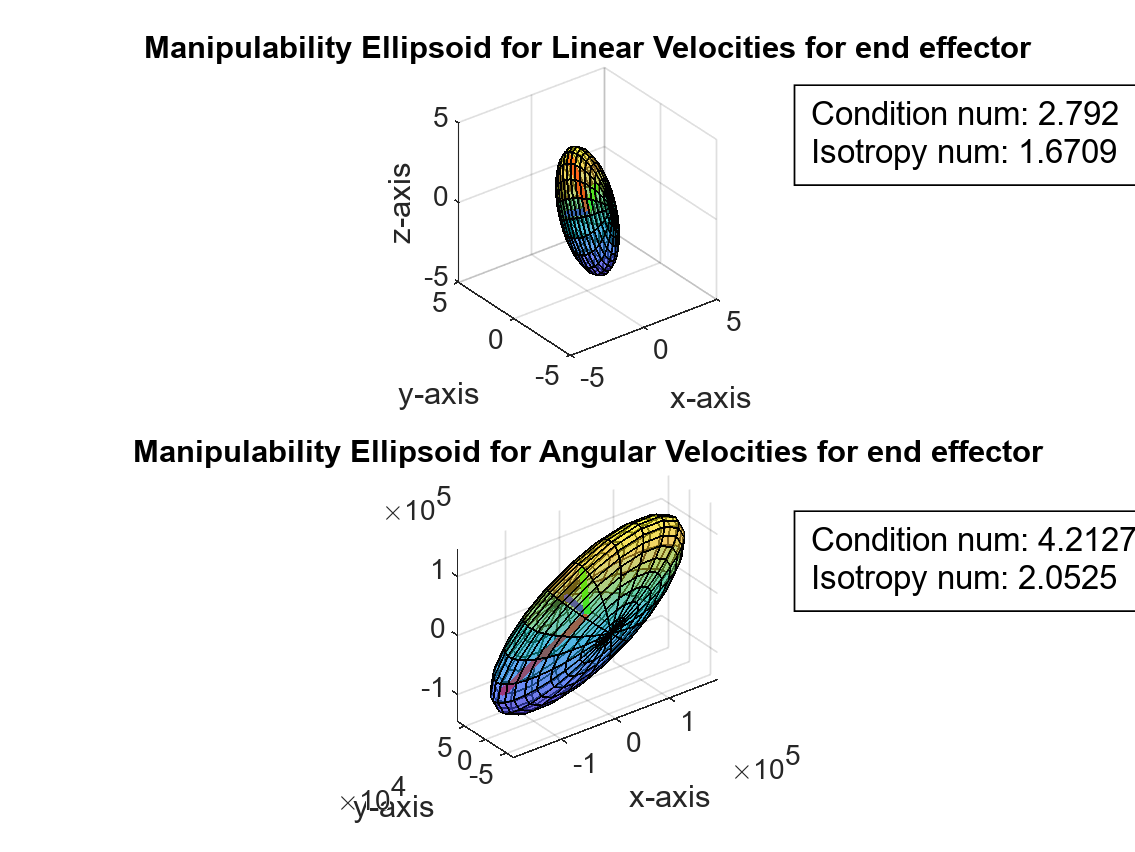

i = 10

theta =    12.4152   12.4588   12.5149   12.5897   12.5897   12.5149   12.4588   12.4152
   38.1768   38.2204   38.2765   38.3513   38.3513   38.2765   38.2204   38.1768
   20.8869   20.9305   20.9866   21.0614   21.0614   20.9866   20.9305   20.8869
 -124.7381 -124.6945 -124.6384 -124.5636 -124.5636 -124.6384 -124.6945 -124.7381
  132.9342  132.9778  133.0339  133.1087  133.1087  133.0339  132.9778  132.9342
  129.6557  129.6993  129.7554  129.8302  129.8302  129.7554  129.6993  129.6557
  -12.0321  -11.9884  -11.9323  -11.8575  -11.8575  -11.9323  -11.9884  -12.0321
   36.7677   36.8113   36.8674   36.9422   36.9422   36.8674   36.8113   36.7677


epsilon_w=1;
epsilon_v=1;

% set initial omega_b and v_b
omega_b=eye(3,3)*2;
v_b=eye(3,3)*2;

%finding Moore-Penrose pseudoinverse Jacobian(J-dagger)

for i=1:10   %this is only until I figure out why it doesnt converge


% while norm(omega_b) > epsilon_w | norm(v_b) > epsilon_v
    %getting body jacobian (I currently only have space function
    Js=J_space(omega,q,home,theta);
    FKsb=FK_space(home, omega,q, theta);
    Jb=Js_to_Jb(Js,FKsb);
    ellipsoid_plot(Jb)
    %Jb=J_body(omega,q,home,theta);
    %testing for singularity
    i
    if rank(Jb) ~= 6
        msg = 'singularity encountered';
        error(msg); 
    end


    %finding J-dagger 
    J_pseudo=Jb.'*((Jb*Jb.')^-1);

    %finding V
    Vb_box=logm(T_sb^-1*T_sd);
    omega_b=[Vb_box(3,2);Vb_box(1,3);Vb_box(2,1)];
    v_b=[Vb_box(1,4);Vb_box(2,4);Vb_box(3,4)];
    V=[omega_b;v_b];

    %calculating difference between current joint angles and
    %predicted joint angles (theta_delta)  
    theta_delta = J_pseudo * V; 
    
    %adding that difference onto the previous theta
    theta=theta+theta_delta
end